clear; clc;

## Consensus of $N$ First Order Subsystems

For a system composed of $N$ identical first order subsystems,

$\dot{\mathbf{x}} = 0\mathbf{x} + I\mathbf{u} + I\mathbf{w}$,

we incentivize consensus with the regulated output

$\mathbf{z} = \left[\begin{array}{c}I-\frac{1}{N}\vec{1}\vec{1}^T\\0\end{array}\right]\mathbf{x} + \left[\begin{array}{c}0\\\gamma I\end{array}\right]\mathbf{u}$,

where $\mathbf{x},\mathbf{u},\mathbf{w}\in\mathbb{R}^N$, $\gamma\in\mathbb{R}$. 

We hope to design a state feedback controller $\mathbf{u}=K\mathbf{x}$ which respects a ring graph communication architecture. The undirected ring graph adjacency matrix is given by

$\mathcal{A} = \left[\begin{array}{cccccc}
1&1&0&\cdots&0&1\\
1&1&1&0&\cdots&0\\
0&1&1&\ddots&\ddots&\vdots\\
\vdots&0&\ddots&\ddots&\ddots&0\\
0&\vdots&\ddots&\ddots&\ddots&1\\
1&0&\cdots&0&1&1
\end{array}\right]$.

It is shown in [Jensen 2022](https://arxiv.org/pdf/2012.04792) that due to spatial invariance, we can analytically find the optimal controller with the sparsity of $\mathcal{A}$ as the SLS controller $K=\Phi^u(\Phi^x)^{-1}$, where


$$\Phi^x = \left[\begin{array}{cccccc}
\phi_0^x&\phi^x_{\pm1}&0&\cdots&0&\phi^x_{\pm1}\\
\phi^x_{\pm1}&\phi_0^x&\phi^x_{\pm1}&0&\cdots&0\\
0&\phi^x_{\pm1}&\phi_0^x&\ddots&\ddots&\vdots\\
\vdots&0&\ddots&\ddots&\ddots&0\\
0&\vdots&\ddots&\ddots&\ddots&\phi^x_{\pm1}\\
\phi^x_{\pm1}&0&\cdots&0&\phi^x_{\pm1}&\phi_0^x
\end{array}\right],~

\Phi^u = \left[\begin{array}{cccccc}
\phi_0^u&\phi^u_{\pm1}&0&\cdots&0&\phi^u_{\pm1}\\
\phi^u_{\pm1}&\phi_0^u&\phi^u_{\pm1}&0&\cdots&0\\
0&\phi^u_{\pm1}&\phi_0^u&\ddots&\ddots&\vdots\\
\vdots&0&\ddots&\ddots&\ddots&0\\
0&\vdots&\ddots&\ddots&\ddots&\phi^u_{\pm1}\\
\phi^u_{\pm1}&0&\cdots&0&\phi^u_{\pm1}&\phi_0^u
\end{array}\right]$$


and $\phi^{x/u}_{0/\pm1}$ are given in (76).

We hope to find a state space realization of $K$ with the same block sparsity structure as $\mathcal{A}$.

First construct transfer function matrices (TFMs) $\Phi^x$ and $\Phi^u$ according to [Jensen 2022](https://arxiv.org/pdf/2012.04792):

%parameters
N = 7; %number of nodes
gamma = 1; %effort/consensus weighting parameter

%scalar values
alpha = sqrt( 2-sqrt(2) );
beta = sqrt( 2+sqrt(2) );

%Phi^x, Phi^u realizations
Ax = [0,1,0;
    0,0,1;
    -alpha*beta/gamma^2, -(alpha*beta+beta*gamma+gamma*alpha)/gamma^2, -(beta+alpha+gamma)/gamma];
Bx0 = [1;(alpha+beta)/(2*gamma)-2;(4*gamma^2+2*sqrt(2)-(alpha+beta)^2)/(2*gamma^2)];
Bx1 = [0;sqrt(2)*(alpha-beta)/(4*gamma);sqrt(2)*(beta^2-alpha^2)/(4*gamma^2)];
Bx = [ Bx1, Bx0, Bx1 ];
Cx = [ 1, 0, 0 ];

Au = Ax;
Bu0 = [(alpha+beta)/(2*gamma)-2;
    -( (alpha+beta)^2 - 4*gamma^2 - 2*sqrt(2) )/(2*gamma^2);
    ( alpha^3+beta^3-4*gamma^3 + 2*(alpha+beta+gamma)*(alpha*beta-sqrt(2)) ) / (2*gamma^3)];
Bu1 = [sqrt(2)*(alpha-beta)/(4*gamma);
    sqrt(2)*(beta^2-alpha^2)/(4*gamma^2);
    sqrt(2)*(alpha^3-beta^3)/(4*gamma^3)];
Bu = [ Bu1, Bu0, Bu1 ];
Cu = Cx;

%construct Phi^x and Phi^u transfer matrices
couple_placement = diag(ones(N-1,1),1) + diag(ones(N-1,1),-1); couple_placement(N,1) = 1; couple_placement(1,N) = 1; %locations of coupling terms

Phix_0 = tf(ss(Ax,Bx0,Cx,0)); Phix_1 = tf(ss(Ax,Bx1,Cx,0));
Phix_tf = eye(N)*Phix_0 + couple_placement*Phix_1;
Phiu_0 = tf(ss(Au,Bu0,Cu,0)); Phiu_1 = tf(ss(Au,Bu1,Cu,0));
Phiu_tf = eye(N)*Phiu_0 + couple_placement*Phiu_1;

Each subsystem has a single scalar state and a single scalar control input. The partitions of $\mathbf{x}$ and $\mathbf{u}$ by node are both then $\vec{1}$.

partition_x = ones(1,N);
partition_u = ones(1,N);

## Constructing Structured Controller Realization

We construct a structured realization of $K$ with the steps shown in the following flow chart:

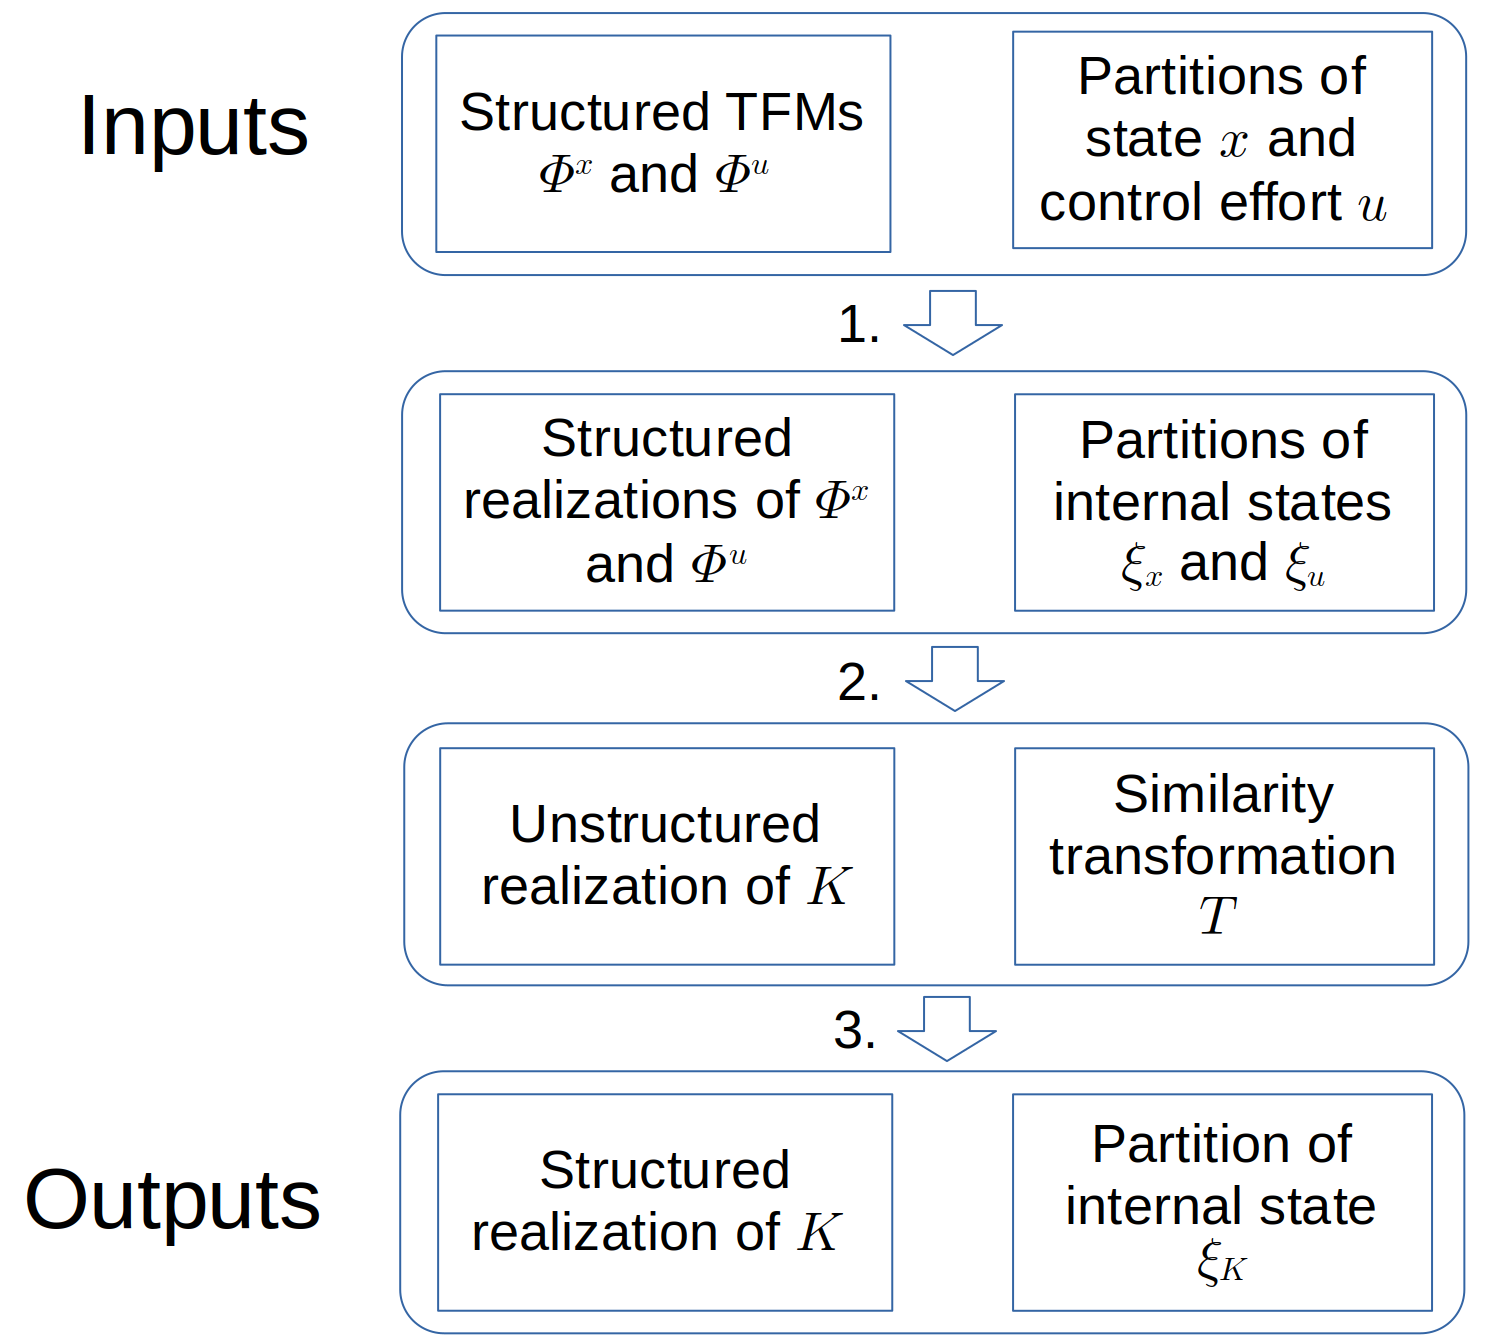

A structured realization of $K$ along with a partition of its internal state $K$ will allow us to implement the controller as $N$ subcontrollers with limited communication.

## Step 1.

In Step 1., we use the inputs, $\Phi^x$, $\Phi^u$ and partitions of $\mathbf{x}$ and $\mathbf{u}$, to create structured realizations of $\Phi^x$ and $\Phi^u$ and partitions of their internal states $\mathbf{\xi_x}$ and $\mathbf{\xi_u}$ respectively.

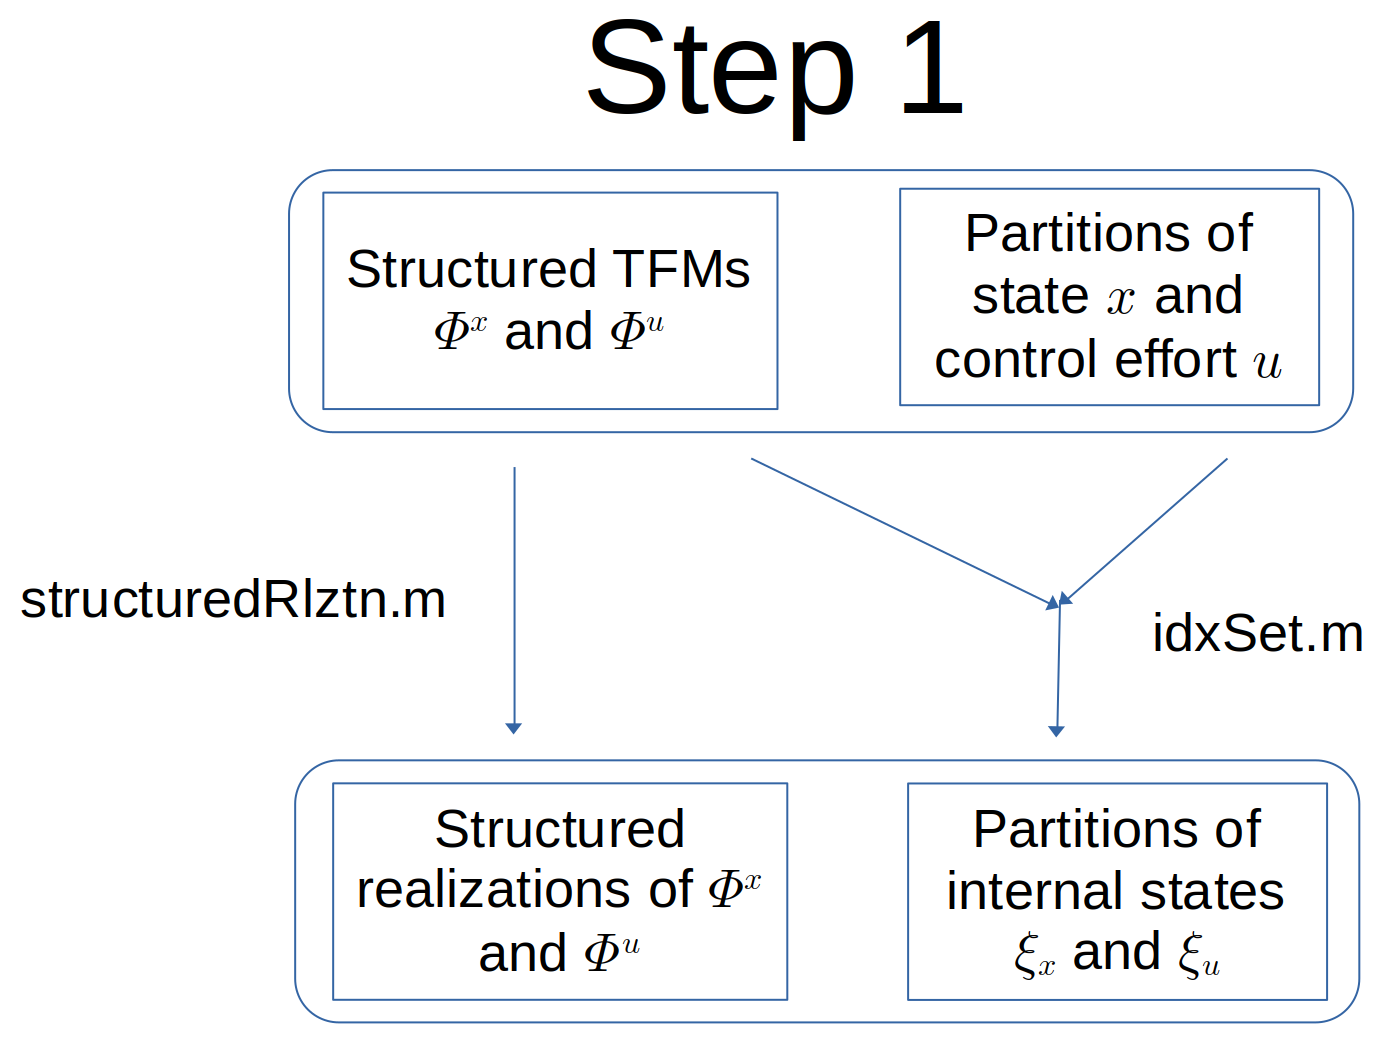

We use the following algorithm to construct a structured realization of a transfer function matrix:

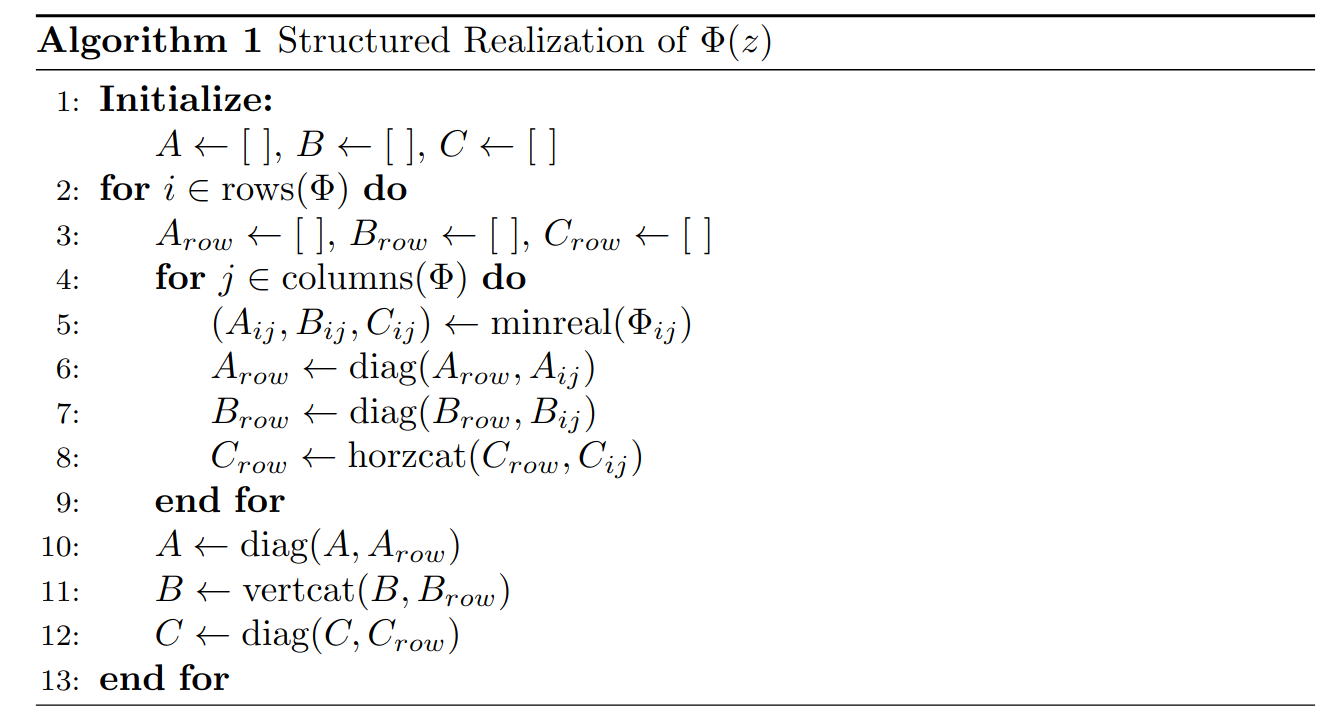

The realization this algorithm creates will have block diagonal $A$ and $C$ and $B$ with the block sparsity of $\mathcal{A}$. We could have used a similar algorithm which gives $A$ and $B$ block diagonal and $C$ with block sparsity of $\mathcal{A}$; it will become clear in Step 2. why choosing $C$ block diagonal is beneficial. This algorithm is implemented in $\texttt{structuredRlztn.m}$.

Phix_ss = structuredRlztn(Phix_tf); Phiu_ss = structuredRlztn(Phiu_tf);

The partition of the internal state for a realization created with this algorithm is simple: the number of states corresponding to a single node is equal to the sum of number states needed to minimally realize each scalar transfer function individually in rows of $\Phi$ corresponding to that node. This is implemented in $\texttt{idxSet.m}$.

partition_ksi_x = idxSet(Phix_ss,partition_x); partition_ksi_u = idxSet(Phiu_ss,partition_u);

We show that these realizations and partitions indeed give block diagonal $A$ and $C$ matrices and $B$ with the block structure of $\mathcal{A}$.

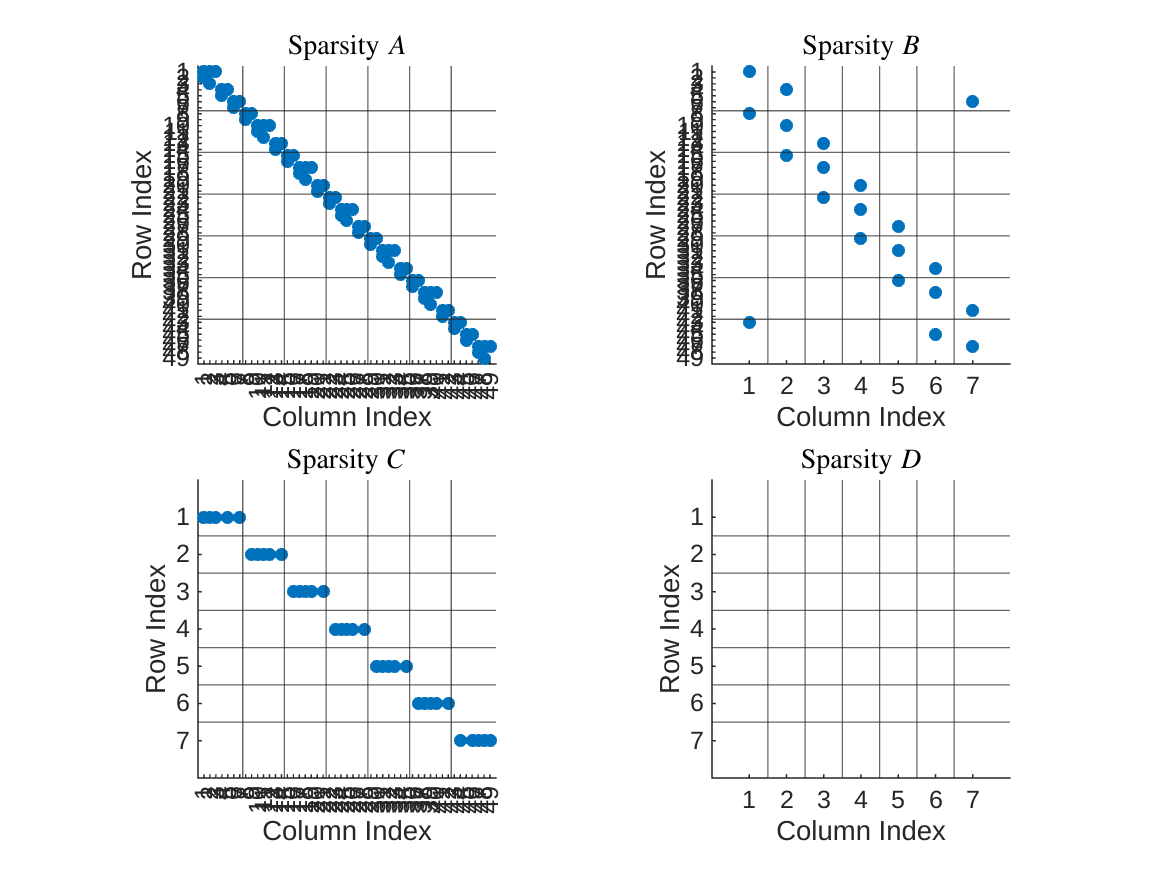

pltBlkSpstyRlztn(Phix_ss,partition_ksi_x,partition_x,partition_x);

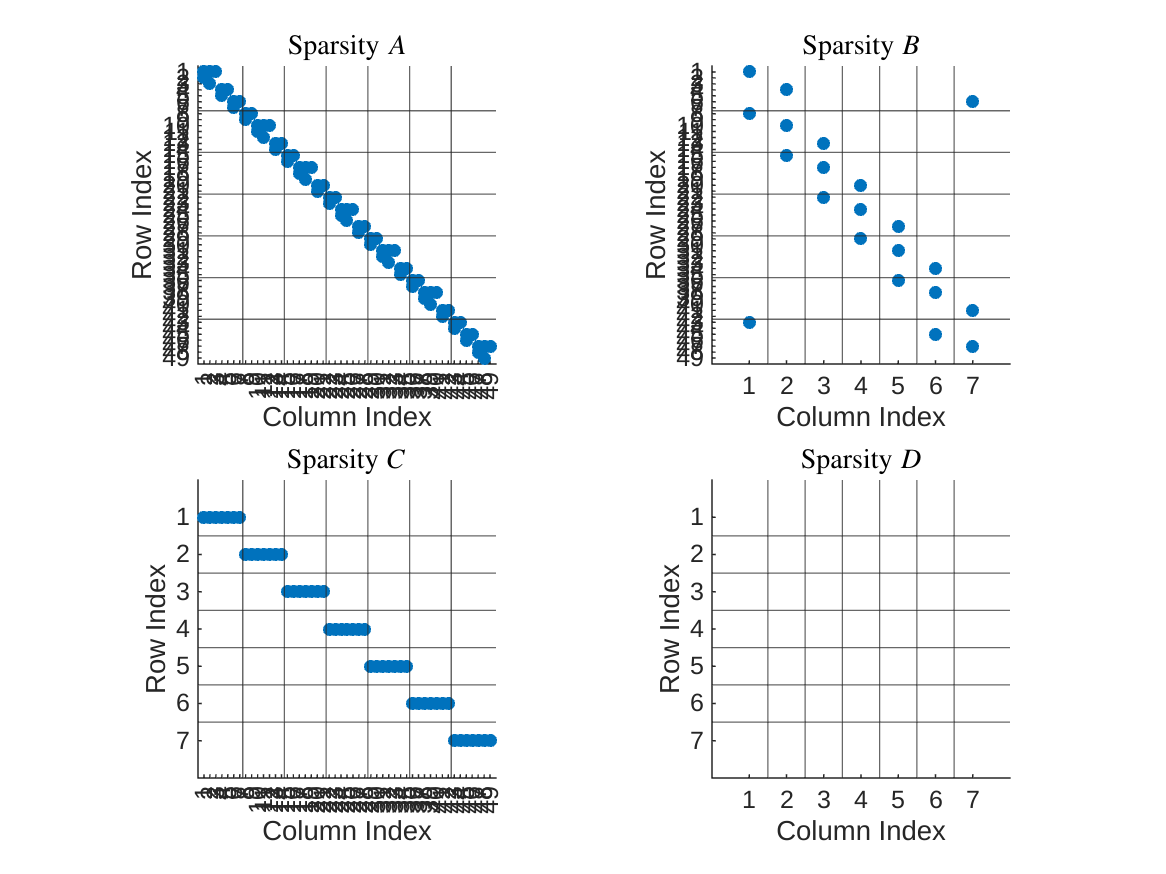

pltBlkSpstyRlztn(Phiu_ss,partition_ksi_u,partition_x,partition_u);

We also demonstrate that the state space realizations of $\Phi^x$ and $\Phi^u$ agree with their original transfer fucntion representations.

ltiEquiv(Phix_tf,Phix_ss);

systems are equivalent to within numerical precision


ltiEquiv(Phiu_tf,Phiu_ss);

systems are equivalent to within numerical precision


## Step 2.

In Step 2., we use the structured realizations $\Phi^x=:\left[\begin{array}{c|c}A_x&B_x\\\hline C_x&0\end{array}\right]$ and $\Phi^u=:\left[\begin{array}{c|c}A_u&B_u\\\hline C_u&0\end{array}\right]$ and the partitions of their internal states to form an unstructured realization of $K$ and a similarity transformation $T$ that will applied in Step 3. to structure $K$.

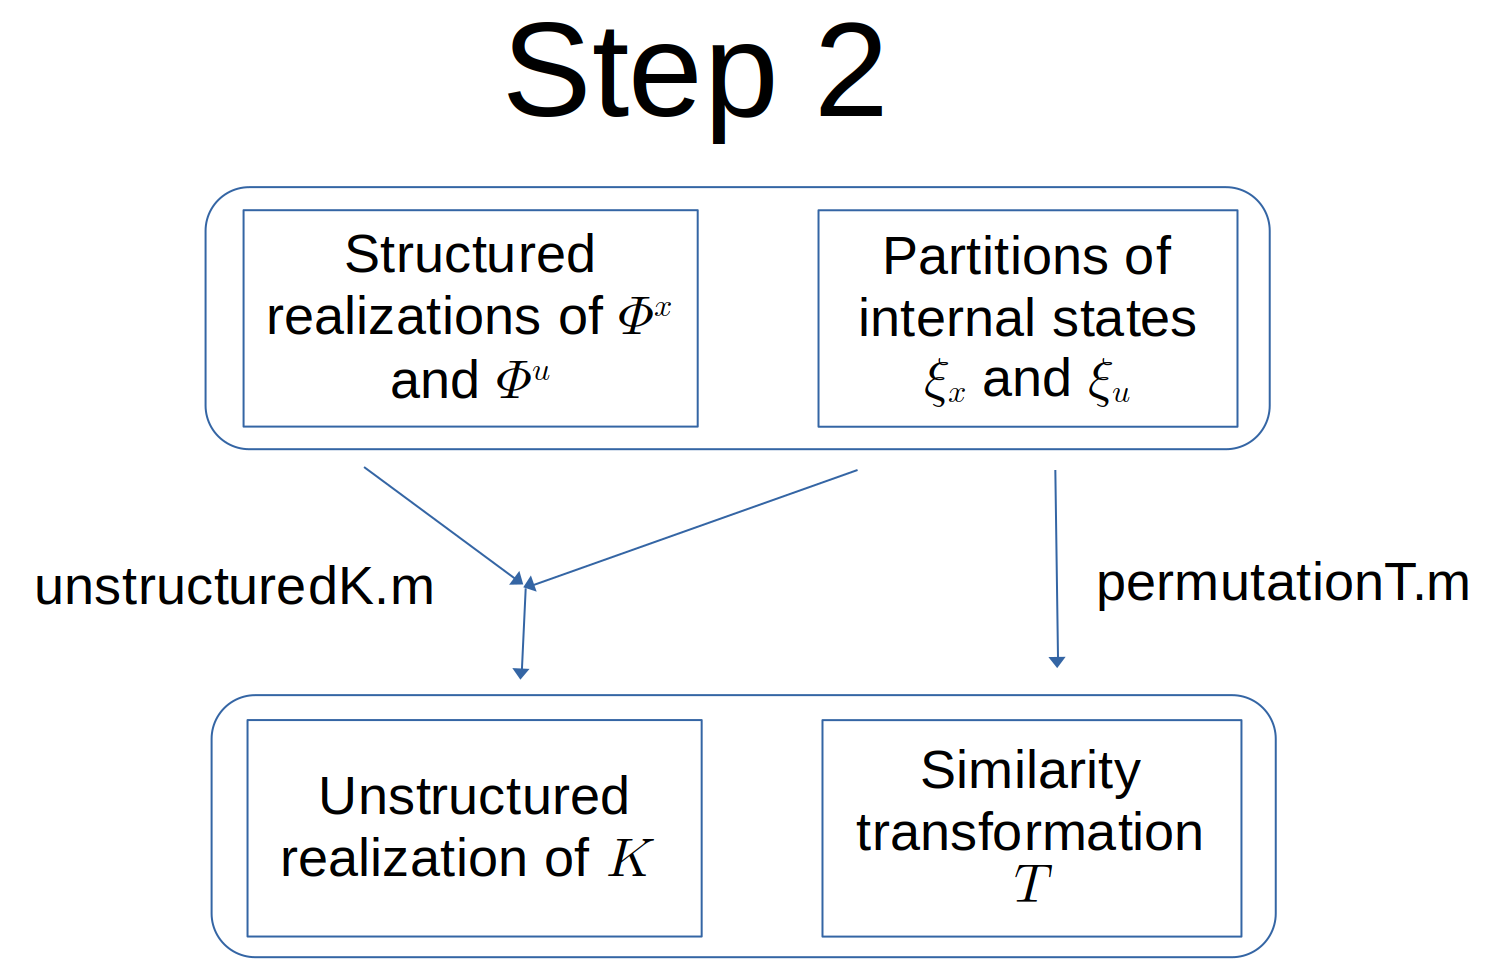

We implement $K$ as the cascade of $[(s+p)\Phi^x]^{-1}$ into $[(s+p)\Phi^u]$ where $p$ is some positive number (this implementation [guarantees stabilizability and detectability](https://www.overleaf.com/read/nvrytmyytmpp#957e75)). A realization of $K$ is given by

$K=[(s+p)\Phi^u][(s+p)\Phi^x]^{-1} = \left[\begin{array}{cc|c}A_x-B_xC_x(A_x+pI) & 0 & B_x\\ -B_uC_x(A_x+pI) & A_u & B_u\\ \hline -C_uB_uC_x(A_x+pI) & C_u(A_u+pI)& C_uB_u\end{array}\right] =: \left[\begin{array}{c|c} A_K & B_K\\ \hline C_K & D_K\end{array}\right]$.

We now see why it was beneficial to choose structured realizations of TFMs with $C$ diagonal rather than $B$ diagonal in Step 1. No element in the realization of $K$ involves more than one $B$ factor, though an element of $C_K$ has two $C$ factors. If we had chosen $C$ to have sparsity $\mathcal{A}$ rather than block diagonal, an element of$C_K$ would have sparsity $\mathcal{A}^2$. With our choice, each element has sparsity at most $\mathcal{A}$.

This realization is implemented with $\texttt{unstructuredK.m}$.

K = unstructuredK(Phiu_ss,Phix_ss,partition_ksi_u,partition_ksi_x,1);

We show that this realization is equivalent to the transfer matrix $\Phi^u(\Phi^x)^{-1}$.

ltiEquiv(K,Phiu_tf/Phix_tf);

systems are equivalent to within numerical precision


The state of this realization is ordered as $\left[\begin{array}{cccccc}\mathbf{\xi_x^1}&\dots&\mathbf{\xi_x^N}&\mathbf{\xi_u^1}&\dots&\mathbf{\xi_u^N}\end{array}\right]^T$. For a structed realization, we want to group states by node, i.e $\left[\begin{array}{ccccc}\mathbf{\xi_x^1}&\mathbf{\xi_u^1}&\dots&\mathbf{\xi_x^N}&\mathbf{\xi_u^N}\end{array}\right]^T$. For illustrative purposes, take $N=3$, with $\mathbf{\xi_x^i}\in\mathbb{R}^{n_i}$ and $\mathbf{\xi_u^i}\in\mathbb{R}^{m_i}$. The transformation $T$ that will perform this desired state permutation is

$T=\left[\begin{array}{c} I^{n_1\times n_1}&0^{n_1\times n_2}&0^{n_1\times n_3}&0^{n_1\times m_1}&0^{n_1\times m_2}&0^{n_1\times m_3}\\0^{m_1\times n_1}&0^{m_1\times n_2}&0^{m_1\times n_3}&I^{m_1\times m_1}&0^{m_1\times m_2}&0^{m_1\times m_3}\\0^{n_2\times n_1}&I^{n_2\times n_2}&0^{n_2\times n_3}&0^{n_2\times m_1}&0^{n_2\times m_2}&0^{n_2\times m_3}\\0^{m_2\times n_1}&0^{m_2\times n_2}&0^{m_2\times n_3}&0^{m_2\times m_1}&I^{m_2\times m_2}&0^{m_2\times m_3}\\0^{n_3\times n_1}&0^{n_3\times n_2}&I^{n_3\times n_3}&0^{n_3\times m_1}&0^{n_3\times m_2}&0^{n_3\times m_3}\\0^{m_3\times n_1}&0^{m_3\times n_2}&0^{m_3\times n_3}&0^{m_3\times m_1}&0^{m_3\times m_2}&I^{m_3\times m_3} \end{array}\right]$.

The function $\texttt{permutationT.m}$ computes this matrix $T$ for the given partitions of $\mathbf{\xi_x}$ and $\mathbf{\xi_u}$.

T = permutationT(partition_ksi_x,partition_ksi_u);

We show that $T$ is the expected form.

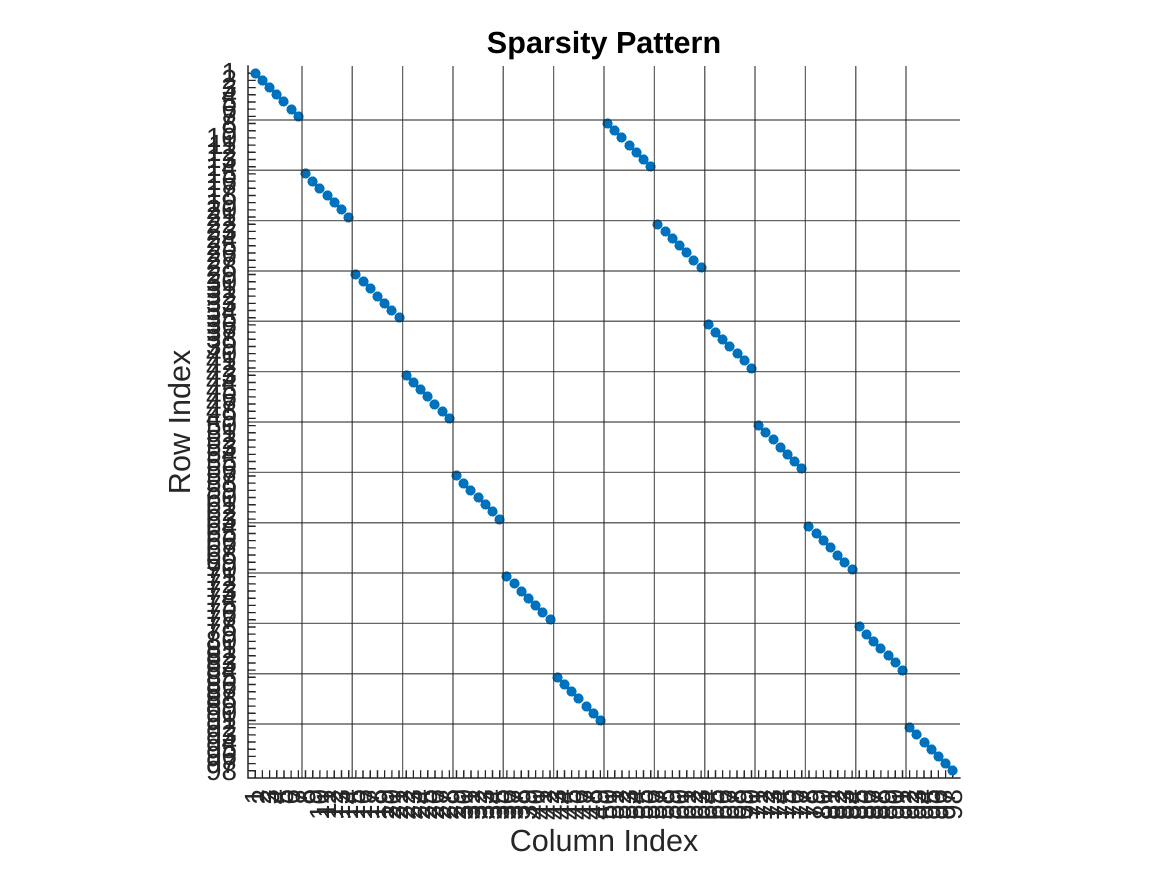

row_partition = reshape([partition_ksi_x partition_ksi_u]', [], 1);
col_partition = [partition_ksi_x;partition_ksi_u];
figure()
pltBlkSpsty(T,row_partition,col_partition)

## Step 3.

In Step 3., we apply the similarity transformation $T$ on the unstructured realization of $K$ to give a structured realization of $K$ and give the partition of the final internal state $\mathbf{\xi_K}$.

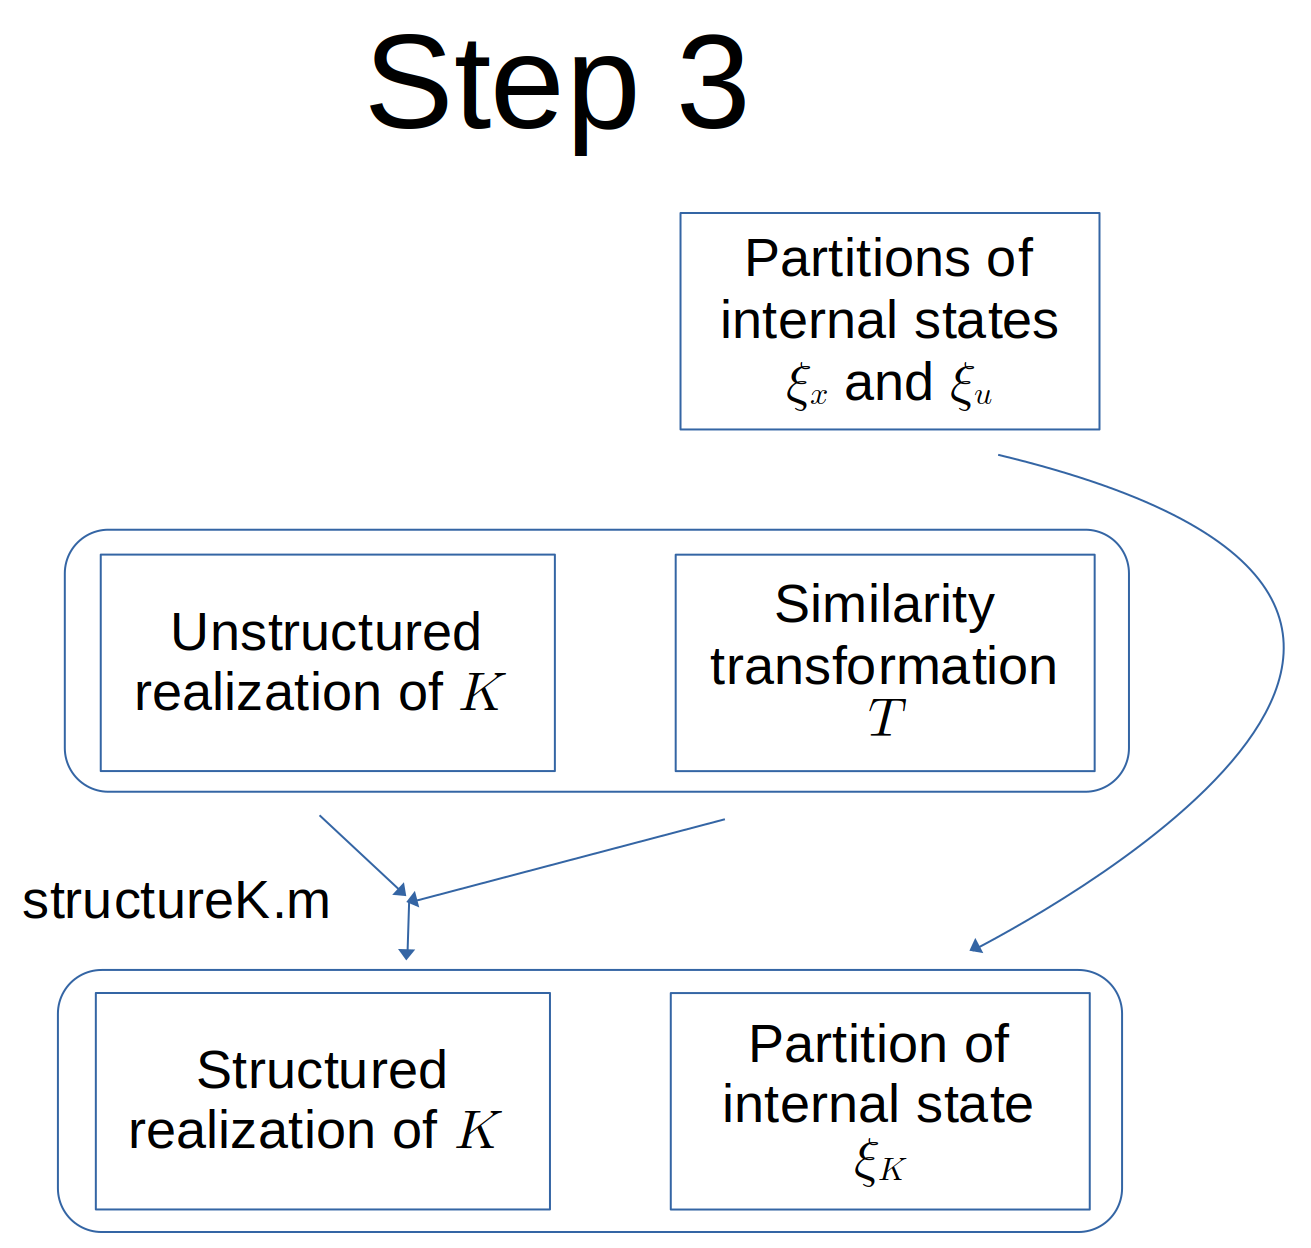

Permuting the states with $T$, the new realization of $K$ will be

$K=\left[\begin{array}{c|c}TA_KT^{-1}&TB_K\\\hline C_KT^{-1}&D_K\end{array}\right]$.

The transformation is applied with $\texttt{structureK.m}$.

K = structureK(K,T);

Since states are now grouped by node, the $i^{th}$ node will have state $\mathbf{\xi_K^i}=\left[\begin{array}{cc}(\mathbf{\xi_x^i})^T&(\mathbf{\xi_u^i})^T\end{array}\right]^T$ which is of size $n_i+m_i$.

partition_ksi_K = partition_ksi_x + partition_ksi_u;

We demonstrate that this realization of $K$ has each of its matrices with block sparsity of $\mathcal{A}$.

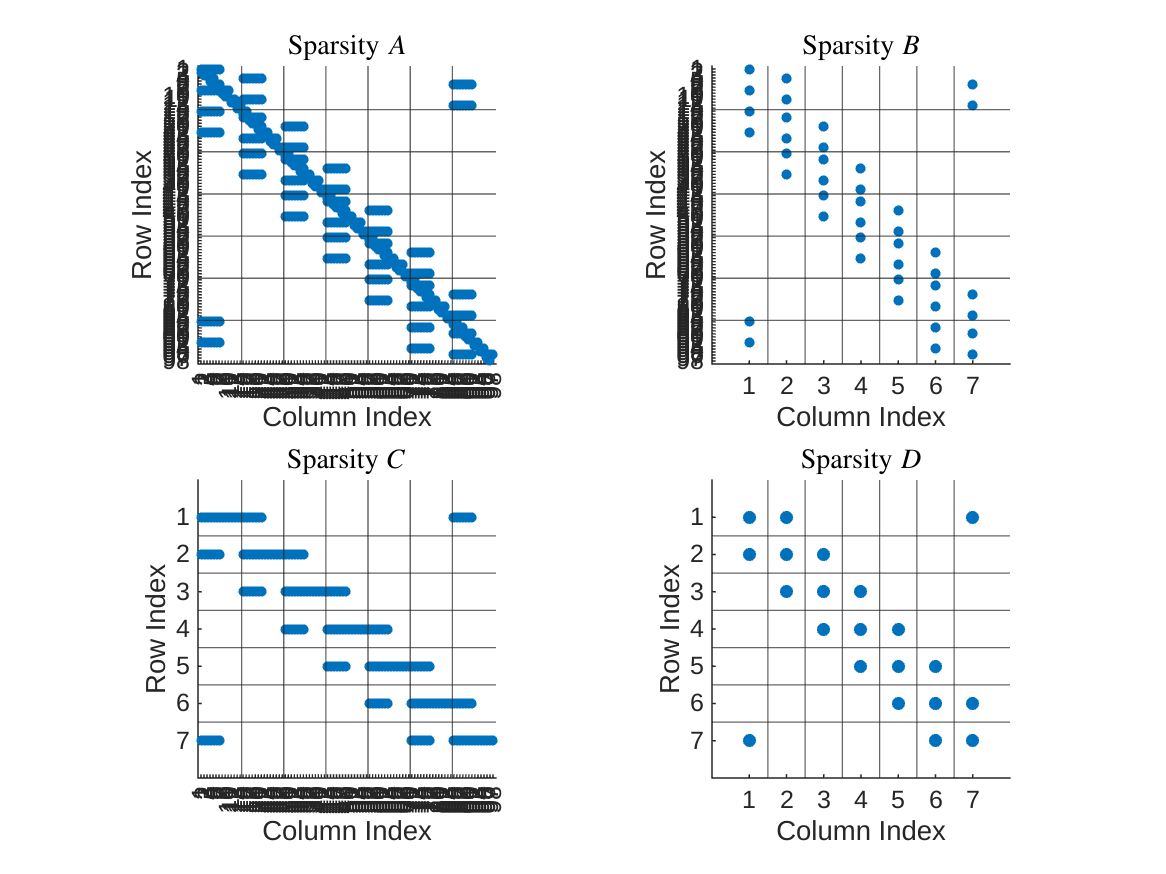

pltBlkSpstyRlztn(K,partition_ksi_K,partition_x,partition_u);

We also show that this realization of $K$ is equivalent to the TFM $\Phi^u(\Phi^x)^{-1}$.

ltiEquiv(K,Phiu_tf/Phix_tf);

systems are equivalent to within numerical precision


We now have a realization we could implement on hardware as subcontrollers with limited communication.